whos G_ident

  Name         Size            Bytes  Class    Attributes

  G_ident      1x1              1302  tf                 




G_noDelay = pade(G_ident,2);
desired_settling = 6;
C_PI = pidtune(G_noDelay,'PI');
C_PI


C_PI =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.31, Ki = 0.425
 
Continuous-time PI controller in parallel form.



C_PID = pidtune(G_noDelay,'PID');
C_PID


C_PID =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.4, Ki = 0.381
 
Continuous-time PI controller in parallel form.


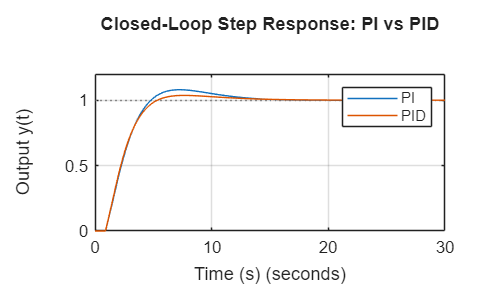


CL_PID = feedback(C_PID * G_ident, 1);
CL_PI = feedback(C_PI * G_ident, 1);

figure
step(CL_PI, CL_PID, 30)
grid on
legend('PI','PID')
title('Closed-Loop Step Response: PI vs PID')
xlabel('Time (s)')
ylabel('Output y(t)')


yss_PI  = dcgain(CL_PI);
yss_PID = dcgain(CL_PID);

results.SteadyStateError = [abs(1 - yss_PI); abs(1 - yss_PID)];
disp(results)

    SteadyStateError: [2×1 double]



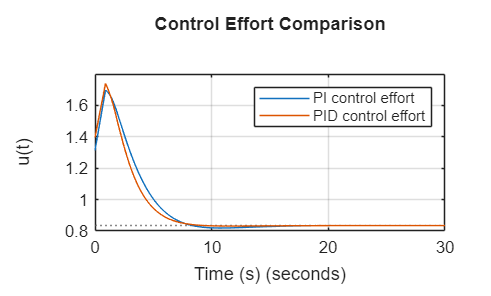


U_PI  = feedback(C_PI,  G_ident);   % from reference to control input
U_PID = feedback(C_PID, G_ident);

figure
step(U_PI, U_PID, 30)
grid on
legend('PI control effort','PID control effort')
title('Control Effort Comparison')
xlabel('Time (s)')
ylabel('u(t)')